## Code used to manually trim the data 

When the data collection is started, the phone still needs to be put in the pocket, causing a big spiky mess in the acceleration data. We manually trimmed down a few seconds on each end of the acceleration data to get rid of this. At least for the 1-step takes this is the case, but for 10 steps+ we didn't trim the data because it was less significant by comparison.

clear all
close all

load sidestance3.mat
Fs=10

Fs = 10

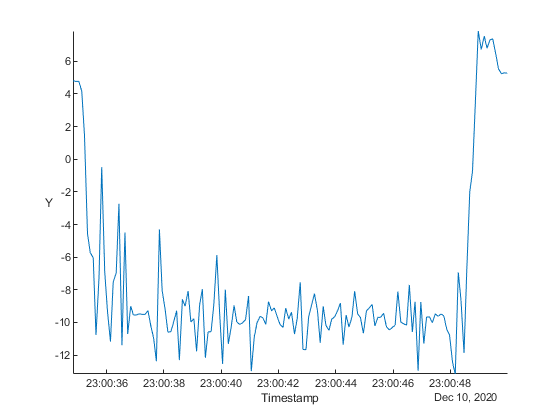

stackedplot(Acceleration(:,"Y"));

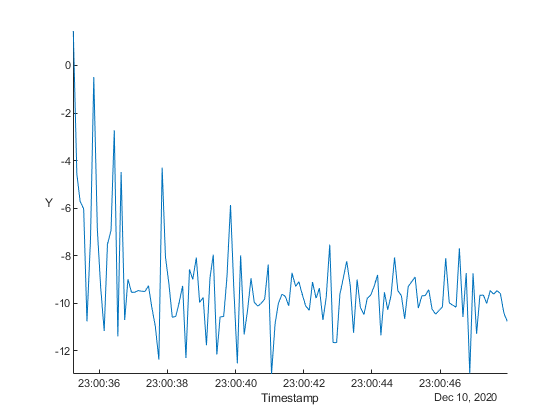

start = .5;
finish = 2;
Acceleration = Acceleration(start*Fs:end-finish*Fs,:);
AngularVelocity = AngularVelocity(start*Fs:end-finish*Fs,:);
Orientation = Orientation(start*Fs:end-finish*Fs,:);
stackedplot(Acceleration(:,"Y"));

% save sidestance3.mat Acceleration Orientation AngularVelocity Fs